# Marcha Patológica

Github: [https://github.com/kooksung/pathological_gait_datasets/tree/master](https://github.com/kooksung/pathological_gait_datasets/tree/master) 

## EDA

clear;
close all;

### Marcha Normal:

% Cargar datos: 
data = readmatrix('human10_normal1_SkeletonData1.xlsx');
% disp('Data: ');
% disp(data);

Los datos tienen la siguiente estructura:


$$time, 0, joint0_x, joint0_y, joint0_z, 1, joint1_x, joint1_y, joint1_z, 2, joint2_x, joint2_y, joint2_z, ...$$


Para determinar que articulación se está manejado, el doi muestra lo siguiente: 

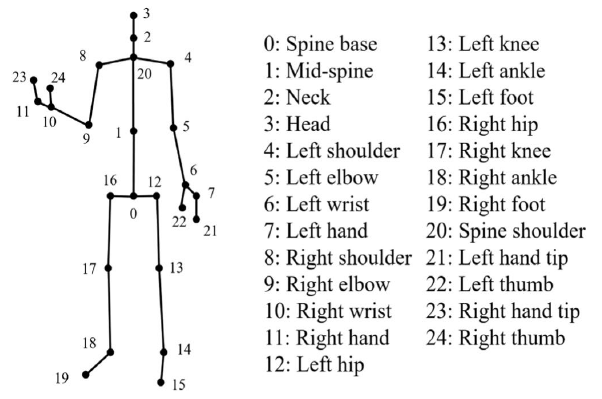

% Definir los nombres base de las 25 articulaciones
jointNames = {'SpineBase', 'MidSpine', 'Neck', 'Head', 'LeftShoulder', ...
    'LeftElbow', 'LeftWrist', 'LeftHand', 'RightShoulder', 'RightElbow', ...
    'RightWrist', 'RightHand', 'LeftHip', 'LeftKnee', 'LeftAnkle', ...
    'LeftFoot', 'RightHip', 'RightKnee', 'RightAnkle', 'RightFoot', ...
    'SpineShoulder', 'LeftHandTip', 'LeftThumb', 'RightHandTip', 'RightThumb'};

% Generar la lista completa de títulos (Headers) para la tabla
% Empezamos con la columna de tiempo
varNames = {'Time'}; 

% Añadimos los sufijos _X, _Y, _Z a cada articulación
for i = 1:length(jointNames)
    name = jointNames{i};
    varNames{end+1} = [name, '_X'];
    varNames{end+1} = [name, '_Y'];
    varNames{end+1} = [name, '_Z'];
end

% Eliminar las columnas de los integers (IDs)
% Los IDs están en las columnas 2, 6, 10, 14... hasta el final
colsToDelete = 2:4:size(data, 2); 
cleanData = data; 
cleanData(:, colsToDelete) = []; 

% Convertir la matriz de datos limpios a una Tabla
dataTable = array2table(cleanData, 'VariableNames', varNames);

% Mostrar las primeras filas de la tabla para verificar
head(dataTable);

     Time     SpineBase_X    SpineBase_Y    SpineBase_Z    MidSpine_X    MidSpine_Y    MidSpine_Z     Neck_X       Neck_Y      Neck_Z     Head_X       Head_Y      Head_Z    LeftShoulder_X    LeftShoulder_Y    LeftShoulder_Z    LeftElbow_X    LeftElbow_Y    LeftElbow_Z    LeftWrist_X    LeftWrist_Y    LeftWrist_Z    LeftHand_X    LeftHand_Y    LeftHand_Z    RightShoulder_X    RightShoulder_Y    RightShoulder_Z    RightElbow_X    RightElbow_Y    RightElbow_Z    R

% 1. Definir las conexiones entre articulaciones (Huesos)
% Cada par de números representa los índices (del 1 al 25) que deben unirse
bones = [
    1, 2; 2, 21; 21, 3; 3, 4; % Tronco y cabeza
    21, 5; 5, 6; 6, 7; 7, 8; 8, 22; 7, 23; % Brazo izquierdo
    21, 9; 9, 10; 10, 11; 11, 12; 12, 24; 11, 25; % Brazo derecho
    1, 13; 13, 14; 14, 15; 15, 16; % Pierna izquierda
    1, 17; 17, 18; 18, 19; 19, 20  % Pierna derecha
    ];

% Crear una figura nueva
% figure('Name', 'Animación de Esqueleto 3D');
% 
% % 2. Bucle de animación: Recorrer todas las filas de la tabla
% for k = 1:height(dataTable)
% 
%     % Extraer la fila actual, saltando la columna 'Time' (columna 1)
%     frameData = table2array(dataTable(k, 2:end)); 
% 
%     % Reestructurar la fila de 75 datos en una matriz de 25x3 (X, Y, Z por fila)
%     joints3D = reshape(frameData, 3, 25)'; 
% 
%     X = joints3D(:, 1);
%     Y = joints3D(:, 2);
%     Z = joints3D(:, 3);
% 
%     % Limpiar el gráfico anterior para dibujar el nuevo
%     cla; 
%     hold on;
%     grid on;
% 
%     % Graficar los puntos (articulaciones)
%     plot3(X, Y, Z, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'b', 'Color', 'b');
% 
%     % Graficar las líneas (huesos)
%     for i = 1:size(bones, 1)
%         j1 = bones(i, 1);
%         j2 = bones(i, 2);
%         plot3([X(j1), X(j2)], [Y(j1), Y(j2)], [Z(j1), Z(j2)], 'k-', 'LineWidth', 2);
%     end
% 
%     % 3. Configurar la vista
%     view(3); % Vista 3D estándar
% 
%     % IMPORTANTE: Ajusta estos límites según el rango de tus datos para que 
%     % la cámara no esté brincando en cada frame.
%     axis([-1 1 -1 4 0 2]); % Formato: [xmin xmax ymin ymax zmin zmax]
% 
%     xlabel('Eje X'); ylabel('Eje Y'); zlabel('Eje Z');
%     title(sprintf('Marcha Normal - Frame: %d | Tiempo: %.2f', k, dataTable.Time(k)));
% 
%     % Pausar brevemente para crear el efecto de video
%     pause(0.03); 
% end

### Marcha Steppage

data_steppage = readmatrix('human1_steppage1_SkeletonData1.csv');
% disp('Data Steppage: '); 
% disp(data_steppage);

cleanData = data_steppage; 
cleanData(:, colsToDelete) = []; 

datasteppageTable = array2table(cleanData, 'VariableNames', varNames);

% head(datasteppageTable);

% Crear una figura nueva
% figure('Name', 'Animación de Esqueleto 3D');
% 
% % 2. Bucle de animación: Recorrer todas las filas de la tabla
% for k = 1:height(datasteppageTable)
%     if k<=80
%         % Extraer la fila actual, saltando la columna 'Time' (columna 1)
%         frameData = table2array(datasteppageTable(k, 2:end)); 
% 
%         % Reestructurar la fila de 75 datos en una matriz de 25x3 (X, Y, Z por fila)
%         joints3D = reshape(frameData, 3, 25)'; 
% 
%         X = joints3D(:, 1);
%         Y = joints3D(:, 2);
%         Z = joints3D(:, 3);
% 
%         % Limpiar el gráfico anterior para dibujar el nuevo
%         cla; 
%         hold on;
%         grid on;
% 
%         % Graficar los puntos (articulaciones)
%         plot3(X, Y, Z, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'Color', 'r');
% 
%         % Graficar las líneas (huesos)
%         for i = 1:size(bones, 1)
%             j1 = bones(i, 1);
%             j2 = bones(i, 2);
%             plot3([X(j1), X(j2)], [Y(j1), Y(j2)], [Z(j1), Z(j2)], 'k-', 'LineWidth', 2);
%         end
% 
%         % 3. Configurar la vista
%         view(3); % Vista 3D estándar
% 
%         % IMPORTANTE: Ajusta estos límites según el rango de tus datos para que 
%         % la cámara no esté brincando en cada frame.
%         axis([-1 1 -1 4 0 2]); % Formato: [xmin xmax ymin ymax zmin zmax]
% 
%         xlabel('Eje X'); ylabel('Eje Y'); zlabel('Eje Z');
%         title(sprintf('Marcha Steppage - Frame: %d | Tiempo: %.2f', k, datasteppageTable.Time(k)));
% 
%         % Pausar brevemente para crear el efecto de video
%         pause(0.03); 
%     end
% end

## Análisis Biomecánico Rápido

% Análisis de ángulo de la cadera respecto al eje x. 
x_axis = [1 0 0];
right_hip = [dataTable.RightHip_X dataTable.RightHip_Y]; % Se ignora la dimensión Z. 
left_hip = [dataTable.LeftHip_X dataTable.LeftHip_Y];
hips_vector = right_hip-left_hip; % Punto final menos punto inicial. 

% Ángulo entre vectores 
hip_angle_rad = atan2(hips_vector(:, 2), hips_vector(:, 1)); 
hip_angle_deg = atan2d(hips_vector(:, 2), hips_vector(:, 1));

right_hip_step = [datasteppageTable.RightHip_X datasteppageTable.RightHip_Y]; % Se ignora la dimensión Z. 
left_hip_step = [datasteppageTable.LeftHip_X datasteppageTable.LeftHip_Y];
hips_vector = right_hip_step-left_hip_step; % Punto final menos punto inicial. 

% Ángulo entre vectores 
hip_angle_step_rad = atan2(hips_vector(1:80, 2), hips_vector(1:80, 1)); 
hip_angle_step_deg = atan2d(hips_vector(1:80, 2), hips_vector(1:80, 1));

% Normalización de tiempos 
t_normal = dataTable.Time-dataTable.Time(1);
t_step = datasteppageTable.Time(1:80)-datasteppageTable.Time(1);

% Gráfico de Comparación
% figure('Name', 'Ángulo de Cadera');
% plot(t_normal, hip_angle_deg, 'b-'); hold on; 
% plot(t_step, hip_angle_step_deg, 'r-');
% xlabel('Tiempo [s]'); 
% ylabel('Inclinación Pélvica [°]');
% title('Inclinación Pélvica: Normal vs Steppage');
% legend('Normal', 'Steppage');
% grid on; 

## Procesamiento de Datos

% Se visualiza la frecuencia de muestreo entre los dos datos. 
diferencias_tiempo = diff(dataTable.Time); 
dt_promedio = mean(diferencias_tiempo);
fs_aprox = 1/dt_promedio; 
disp('Frecuencia de muestreo aproximada (Normal): '); 

Frecuencia de muestreo aproximada (Normal): 


disp(fs_aprox);

   30.0038




diff_temp_step = diff(datasteppageTable.Time); 
dt_promedio_step = mean(diff_temp_step);
fs_aprox_step = 1/dt_promedio_step; 
disp('Frecuencia de muestreo aproximada (Steppage): '); 

Frecuencia de muestreo aproximada (Steppage): 


disp(fs_aprox_step);

   28.7942



% Normalización a una frecuencia de muestreo: 
% 1. Definir la frecuencia objetivo para AMBOS sets de datos
fs_objetivo = 30; % Hz exactos
dt_objetivo = 1 / fs_objetivo; % El paso de tiempo constante (0.0333s)

% ==========================================
% PROCESAMIENTO: MARCHA NORMAL
% ==========================================
% Vector original de tiempo (empezando en 0)
t_normal_orig = dataTable.Time - dataTable.Time(1); 

% Nuevo vector de tiempo perfecto a 30 Hz
t_normal_uniforme = 0 : dt_objetivo : t_normal_orig(end); 

% Interpolar a la nueva frecuencia
hip_normal_uniforme = interp1(t_normal_orig, hip_angle_deg, t_normal_uniforme, 'spline');

% ==========================================
% PROCESAMIENTO: MARCHA STEPPAGE
% ==========================================
% Vector original de tiempo (empezando en 0)
t_step_orig = datasteppageTable.Time(1:80) - datasteppageTable.Time(1); 

% Nuevo vector de tiempo perfecto a 30 Hz
t_step_uniforme = 0 : dt_objetivo : t_step_orig(end); 

% Interpolar a la nueva frecuencia
hip_step_uniforme = interp1(t_step_orig, hip_angle_step_deg, t_step_uniforme, 'spline');

## Filtraje

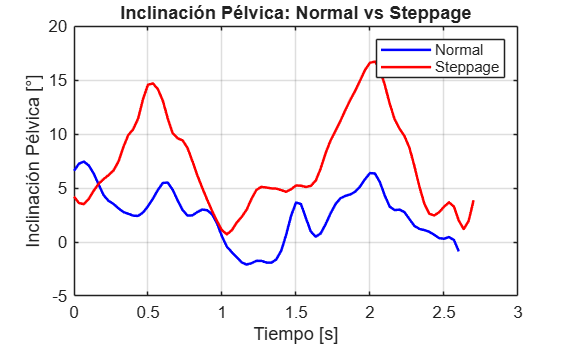

fc = 6; % Frecuencia de corte de 6 Hz
[b, a] = butter(2, fc / (fs_objetivo / 2), 'low');

hip_normal_filtrada = filtfilt(b, a, hip_normal_uniforme);
hip_step_filtrada = filtfilt(b, a, hip_step_uniforme);

figure('Name', 'Inclinación Pélvica Filtrada');
plot(t_normal_uniforme, hip_normal_filtrada, 'b-', 'LineWidth', 1.5); hold on;
plot(t_step_uniforme, hip_step_filtrada, 'r-', 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Inclinación Pélvica [°]');
title('Inclinación Pélvica: Normal vs Steppage');
legend('Normal', 'Steppage');
grid on;

% Asumimos que vas a procesar tu 'dataTable' (marcha normal)
% Primero, separamos solo las 75 columnas de datos (sin el Tiempo)
dataMatrix = dataTable{:, 2:end}; 
originalNames = dataTable.Properties.VariableNames(2:end);

numVars = size(dataMatrix, 2); % Debería ser 75
numFeatures = 5; % Max, Min, ROM, Mean, Std

% Pre-asignar espacio para velocidad
extractedFeatures = zeros(1, numVars * numFeatures);
newFeatureNames = cell(1, numVars * numFeatures);

colIndex = 1;

for i = 1:numVars
    signal = dataMatrix(:, i); % Extraer la columna completa
    varName = originalNames{i};

    % 1. Calcular las características
    f_max = max(signal);
    f_min = min(signal);
    f_rom = f_max - f_min;
    f_mean = mean(signal);
    f_std = std(signal);

    % 2. Guardar los valores en nuestra nueva fila
    extractedFeatures(colIndex : colIndex+4) = [f_max, f_min, f_rom, f_mean, f_std];

    % 3. Generar los nombres automáticamente
    newFeatureNames{colIndex} = [varName, '_Max'];
    newFeatureNames{colIndex+1} = [varName, '_Min'];
    newFeatureNames{colIndex+2} = [varName, '_ROM'];
    newFeatureNames{colIndex+3} = [varName, '_Mean'];
    newFeatureNames{colIndex+4} = [varName, '_Std'];

    colIndex = colIndex + 5;
end

% Convertir la fila resultante en una tabla final
featuresTable = array2table(extractedFeatures, 'VariableNames', newFeatureNames);

% Agregar la etiqueta (Target) al final para el Machine Learning
featuresTable.Clase = "Normal"; % O "Steppage" para tu otra tabla

## Análisis Biomecánico

De acuerdo con el random forest, estas son las variables más significativas para el Steppage:

important_variables = {'RightKnee_Z_Max';'RightKnee_Z_Std';'RightAnkle_Z_Std';'RightAnkle_Z_Max';'RightKnee_Z_ROM';'LeftHandTip_Z_Mean';'Head_X_Min';'RightAnkle_Z_Mean';'Neck_X_Std';'LeftThumb_Z_Min';'RightFoot_Z_Std';'Head_X_Mean';'RightFoot_Z_Mean';'Neck_X_Min';'LeftHand_Z_Std'};

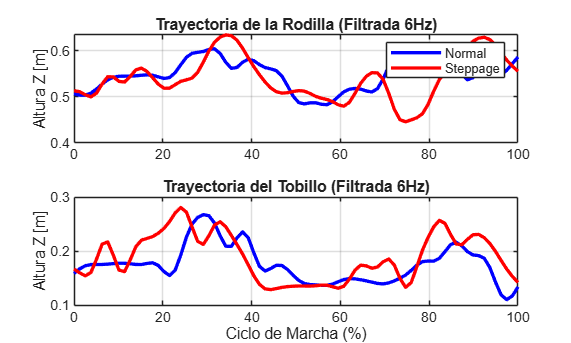

% =====================================================
% Filtrado Butterworth y Visualización de Marcha Limpia
% =====================================================

% 1. Configuración del Filtro (Pasa-bajos 6 Hz)
fs = 30; % Frecuencia de muestreo típica (Kinect/Cámaras)
fc = 6;  % Frecuencia de corte
[b, a] = butter(4, fc/(fs/2)); % Filtro de 4to orden

% 2. Filtrado de Señales (Knee y Ankle son las más importantes)
% Rodilla
knee_norm_f = filtfilt(b, a, dataTable.RightKnee_Z);
knee_step_f = filtfilt(b, a, datasteppageTable.RightKnee_Z(1:80));

% Tobillo
ankle_norm_f = filtfilt(b, a, dataTable.RightAnkle_Z);
ankle_step_f = filtfilt(b, a, datasteppageTable.RightAnkle_Z(1:80));

% 3. Normalización de Ciclo (0-100%)
t_norm = linspace(0, 100, length(knee_norm_f));
t_step = linspace(0, 100, length(knee_step_f));

% 4. Creación de la Gráfica Comparativa
figure('Name', 'Cinemática Filtrada: Rodilla vs Tobillo', 'Color', 'w');

% --- Subplot 1: Rodilla ---
subplot(2, 1, 1);
plot(t_norm, knee_norm_f, 'b', 'LineWidth', 2); hold on;
plot(t_step, knee_step_f, 'r', 'LineWidth', 2);
title('Trayectoria de la Rodilla (Filtrada 6Hz)');
ylabel('Altura Z [m]');
grid on;
legend('Normal', 'Steppage');

% --- Subplot 2: Tobillo ---
subplot(2, 1, 2);
plot(t_norm, ankle_norm_f, 'b', 'LineWidth', 2); hold on;
plot(t_step, ankle_step_f, 'r', 'LineWidth', 2);
title('Trayectoria del Tobillo (Filtrada 6Hz)');
xlabel('Ciclo de Marcha (%)');
ylabel('Altura Z [m]');
grid on;

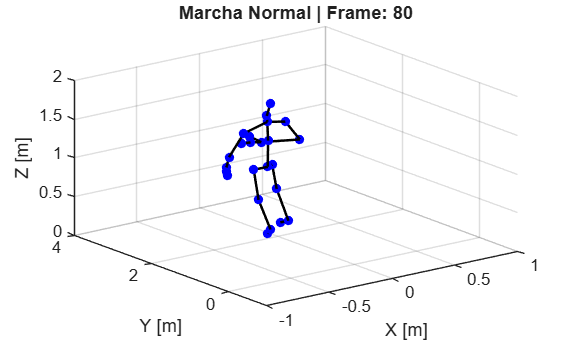

% =====================================================
% ANIMACIÓN 3D DE MARCHA FILTRADA (CALIDAD PROFESIONAL)
% =====================================================

% % 1. Configuración del Filtro (Mismo que usamos anteriormente)
% fs = 30; 
% fc = 6; 
% [b, a] = butter(4, fc/(fs/2));
% 
% % 2. Filtrado de TODA la matriz de datos (75 columnas de articulaciones)
% % Filtramos la marcha Normal
% dataMatrix_norm = table2array(dataTable(:, 2:end));
% data_norm_f = filtfilt(b, a, dataMatrix_norm);
% 
% % Filtramos la marcha Steppage (Primeros 80 frames)
% dataMatrix_step = table2array(datasteppageTable(1:80, 2:end));
% data_step_f = filtfilt(b, a, dataMatrix_step);
% 
% % 3. Función de Animación (Para no repetir código)
% % Definimos los huesos nuevamente para asegurar que estén en el workspace
% bones = [1,2; 2,21; 21,3; 3,4; 21,5; 5,6; 6,7; 7,8; 8,22; 7,23; ...
%     21,9; 9,10; 10,11; 11,12; 12,24; 11,25; 1,13; 13,14; 14,15; 15,16; ...
%     1,17; 17,18; 18,19; 19,20];
% 
% % --- ANIMACIÓN: MARCHA NORMAL FILTRADA ---
% figure('Name', 'Marcha Normal - Filtrada 6Hz', 'Color', 'w');
% for k = 1:size(data_norm_f, 1)
%     joints3D = reshape(data_norm_f(k, :), 3, 25)';
%     X = joints3D(:, 1); Y = joints3D(:, 2); Z = joints3D(:, 3);
% 
%     cla; hold on; grid on;
%     plot3(X, Y, Z, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'b', 'Color', 'b'); % Azul para Normal
%     for i = 1:size(bones, 1)
%         plot3([X(bones(i,1)), X(bones(i,2))], [Y(bones(i,1)), Y(bones(i,2))], ...
%             [Z(bones(i,1)), Z(bones(i,2))], 'k-', 'LineWidth', 1.5);
%     end
%     view(3); axis([-1 1 -1 4 0 2]);
%     xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
%     title(sprintf('Marcha Normal | Frame: %d', k));
%     pause(0.03);
% end

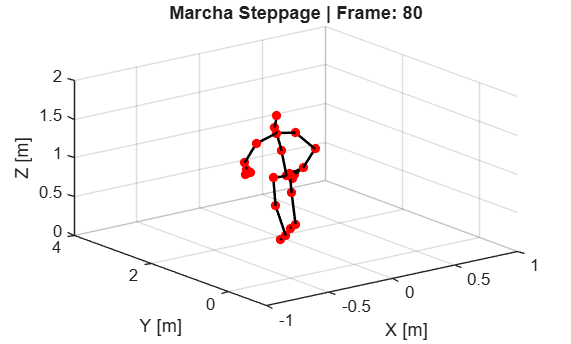

% % --- ANIMACIÓN: MARCHA STEPPAGE FILTRADA ---
% figure('Name', 'Marcha Steppage - Filtrada 6Hz', 'Color', 'w');
% for k = 1:size(data_step_f, 1)
%     joints3D = reshape(data_step_f(k, :), 3, 25)';
%     X = joints3D(:, 1); Y = joints3D(:, 2); Z = joints3D(:, 3);
% 
%     cla; hold on; grid on;
%     plot3(X, Y, Z, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'Color', 'r'); % Rojo para Steppage
%     for i = 1:size(bones, 1)
%         plot3([X(bones(i,1)), X(bones(i,2))], [Y(bones(i,1)), Y(bones(i,2))], ...
%             [Z(bones(i,1)), Z(bones(i,2))], 'k-', 'LineWidth', 1.5);
%     end
%     view(3); axis([-1 1 -1 4 0 2]);
%     xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
%     title(sprintf('Marcha Steppage | Frame: %d', k));
%     pause(0.03);
% end

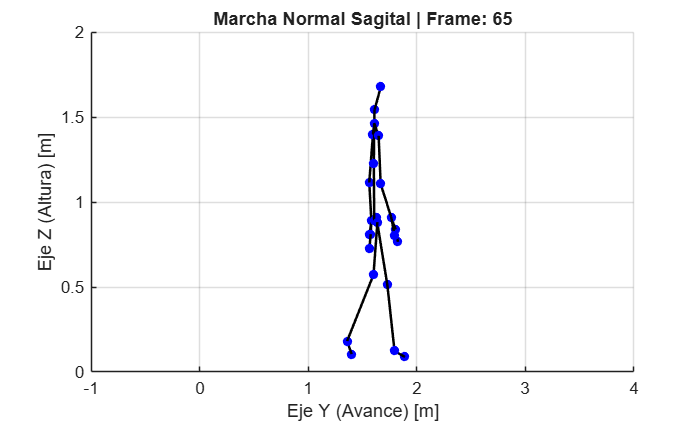

% % =====================================================
% % ANIMACIÓN VISTA SAGITAL (PLANO YZ) - DATOS FILTRADOS
% % =====================================================
% 
% % --- ANIMACIÓN: MARCHA NORMAL (VISTA SAGITAL) ---
% figure('Name', 'Marcha Normal - Vista Sagital', 'Color', 'w');
% for k = 1:size(data_norm_f, 1)
%     joints3D = reshape(data_norm_f(k, :), 3, 25)';
%     X = joints3D(:, 1); Y = joints3D(:, 2); Z = joints3D(:, 3);
% 
%     cla; hold on; grid on;
%     plot3(X, Y, Z, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'b', 'Color', 'b'); 
%     for i = 1:size(bones, 1)
%         plot3([X(bones(i,1)), X(bones(i,2))], [Y(bones(i,1)), Y(bones(i,2))], ...
%             [Z(bones(i,1)), Z(bones(i,2))], 'k-', 'LineWidth', 1.5);
%     end
% 
%     view(90, 0); % Azimut 90°, Elevación 0° (Plano YZ)
% 
%     axis([-1 1 -1 4 0 2]); % Mantenemos los mismos límites para estabilidad
%     xlabel('Eje X (Profundidad)'); ylabel('Eje Y (Avance) [m]'); zlabel('Eje Z (Altura) [m]');
%     title(sprintf('Marcha Normal Sagital | Frame: %d', k));
%     pause(0.03);
% end

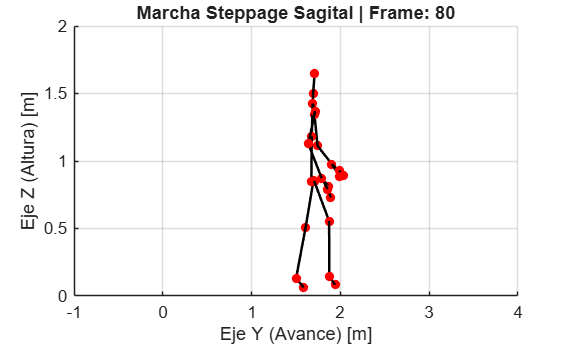

% % --- ANIMACIÓN: MARCHA STEPPAGE (VISTA SAGITAL) ---
% figure('Name', 'Marcha Steppage - Vista Sagital', 'Color', 'w');
% for k = 1:size(data_step_f, 1)
%     joints3D = reshape(data_step_f(k, :), 3, 25)';
%     X = joints3D(:, 1); Y = joints3D(:, 2); Z = joints3D(:, 3);
% 
%     cla; hold on; grid on;
%     plot3(X, Y, Z, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'Color', 'r'); 
%     for i = 1:size(bones, 1)
%         plot3([X(bones(i,1)), X(bones(i,2))], [Y(bones(i,1)), Y(bones(i,2))], ...
%             [Z(bones(i,1)), Z(bones(i,2))], 'k-', 'LineWidth', 1.5);
%     end
% 
%     view(90, 0); % Azimut 90°, Elevación 0° (Plano YZ)
% 
%     axis([-1 1 -1 4 0 2]); % Mantenemos los mismos límites para estabilidad
%     xlabel('Eje X (Profundidad)'); ylabel('Eje Y (Avance) [m]'); zlabel('Eje Z (Altura) [m]');
%     title(sprintf('Marcha Steppage Sagital | Frame: %d', k));
%     pause(0.03);
% end